t_samples = (0:4:120)+eps;

TC_1 = zeros(10,10,10, length(t_samples));
k_1 = 0.2.*rand(10,10,10);          % local diffusion-related parameter (0.35<)
mu_1 = 2.5/k_1 ;    % mean transit time (lambda/k)
alpha_1 = 1;        % scale parameter ()
for idx = 1:length(t_samples)
    t = t_samples(idx);  
    TC_1(:,:,:, idx) = alpha_1 .* sqrt(k_1 ./ (2 * pi * t)) .*exp(-((k_1 .* (t - mu_1).^2) ./ (2 * t)));
end

TC_2 = zeros(4,4,4, length(t_samples));
TC_3 = zeros(4,4,4, length(t_samples));
k_2 = 0.5 + (0.65-0.5).*rand(4,4,4);  
mu_2 = 4.5/k_2 ;    
alpha_2 = 0.52;   
k_3 = 0.6 + (0.8-0.6).*rand(4,4,4);  
mu_3 = 6/k_3;    
alpha_3 = 0.6;  
for idx = 1:length(t_samples)
    t = t_samples(idx);  
    TC_2(:,:,:, idx) = alpha_2 .* sqrt(k_2./(2*pi*t)).*exp(-((k_2.*(t - mu_2).^2)./(2 * t))); %TC_2
    TC_3(:,:,:, idx) = alpha_3 .* sqrt(k_3./(2*pi*t)).*exp(-((k_3.*(t - mu_3).^2)./(2 * t))); %TC_3
end

G = TC_1; 
G(2:5,2:5,2:5,:) = TC_2;
G(2:5,6:9,6:9,:) = TC_3;

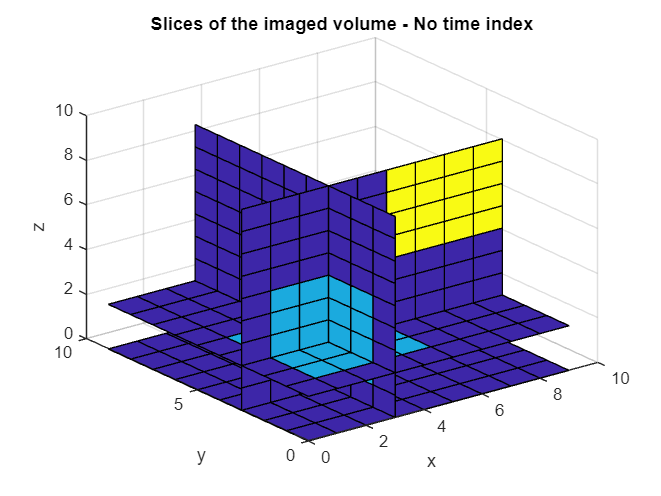

%%%% Slicing volume visual

G_test=zeros(10,10,10);
G_test(2:5,2:5,2:5,:) = 2;
G_test(2:5,6:9,6:9,:) = 5;

x=0:1:9;
y=0:1:9;
z=0:1:9;

[x,y,z]=meshgrid(x,y,z);

xslice = [3,3,3];    % location of y-z planes
yslice = 3;          % location of x-z plane
zslice = [2,0];         % location of x-y planes

figure();
slice(x,y,z,G_test,xslice,yslice,zslice)
xlabel('x')
ylabel('y')
zlabel('z')
title('Slices of the imaged volume - No time index')

noise_param = 10^-4

noise_param = 1.0000e-04

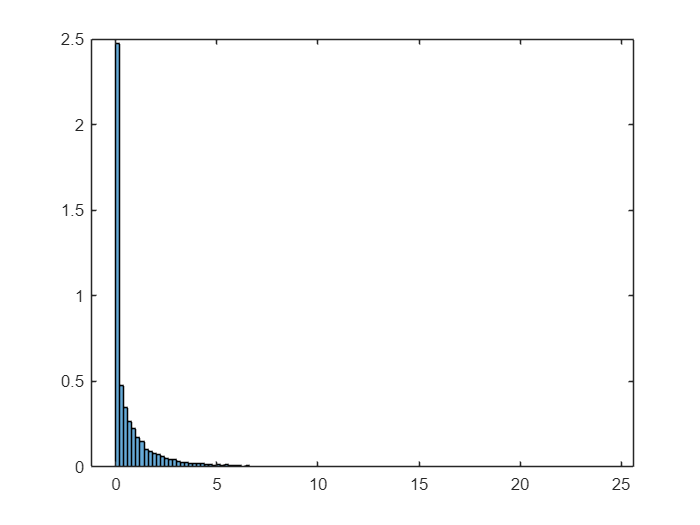

N = raylrnd(noise_param, [10,10,10,length(t_samples)]);
Y = G.*N; 

figure;
histogram(Y*1e6,'Normalization','pdf')

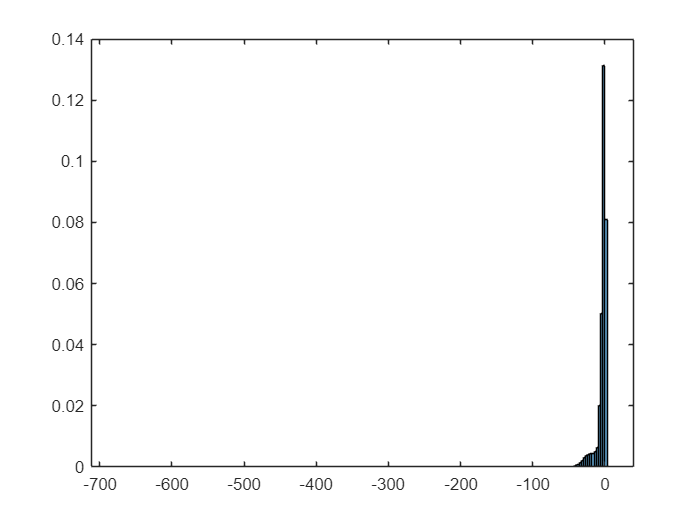

log_Y=log(Y*1e6);

figure;
hist=histogram(log_Y,'Normalization','pdf');

[Ns, Edges]=histcounts(log_Y,'Normalization','probability');
